# Clustering with K-means++

input remote-sensing data [zy3] (multispectrum)

%% read the data zy3sample1
Img = multibandread('zy3sample1',[400,400,4],'float',0,'bsq','n',{'Band','Direct',[1:4]});% input multispectrum
test_class=1:4;
C=length(test_class);
NbRow=400;
NbCol=400;
NbDim=4;
dataname='zy3';

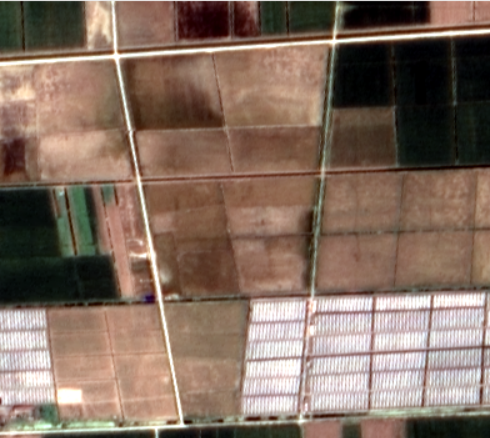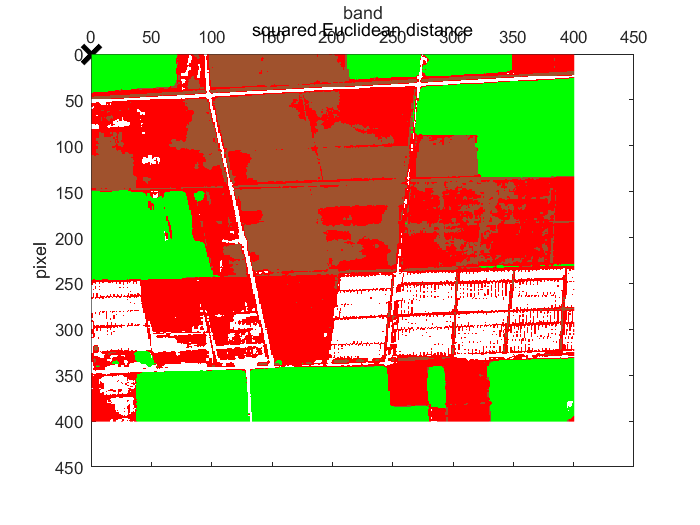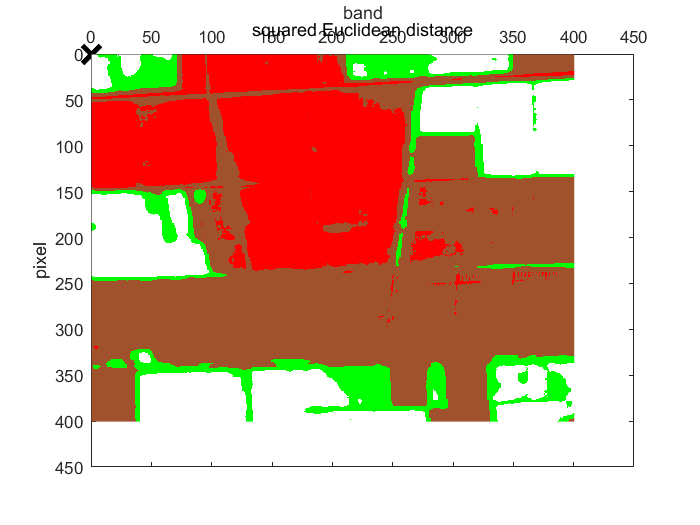

               R3G2B1 multispectrum                          squared Euclidean distance                                  Spectra Angle Mapper

dimensional reduction for parameter-parallel with K-means++ function

for i=1:NbDim  
X(:,i)=reshape(Img(:,:,i),NbRow*NbCol,1);   % allocate new blocks of memory if necessary
end

% other possible solution
%choosing attrs , here we use a* and b* values
% lab_img = rgb2lab(Img);    %convert the image to color space using rgb2lab , using attrs : luminosity , red-green axis , blue-yellow axis    


%  result=kmeans(X,4);
%  [result,center]=My_kmeans(X,4);        %center represents the (k,v) pair for centroid center for each 4 clusters (4*4)
[result,center] = my_kmeans_x(X);

%% plot the classification result of the whole image
 ColorTable=[160,82,45;0 255 0;255, 255, 255;255,0,0];
 ClassificationMap  = GenerateClassificationMap( size(Img,1), size(Img,2), ColorTable, reshape(result',size(Img,1)*size(Img,2),1));
 figure
 centroid_plot = plot(center(:,1),center(:,2),center(:,3),center(:,4),'kx',...
     'MarkerSize',15,'LineWidth',3)

centroid_plot =   2×1 Line 数组:

  Line
  Line


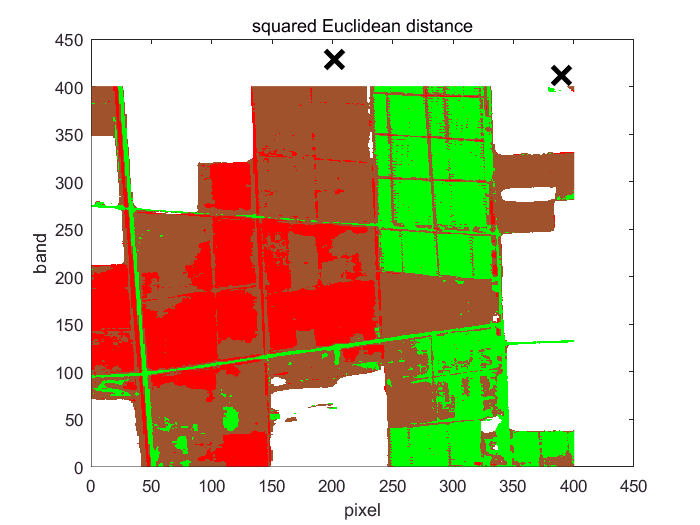

 %  legend(centroid_plot , 'Centroid')
 hold on
 image(ClassificationMap);  axis on;
 title 'squared Euclidean distance';
 xlabel 'pixel';
 ylabel 'band';

 
%  figure
%  silhouette(X,result)

specification:using default metric:`'Euclidean' , showing elements for each cluster is relatively high and acceptable.`

% imwrite(ClassificationMap, [dataname,'_ClusterMap.bmp'], 'bmp'); % save as bmp
% multibandwrite(ClassificationMap,[dataname,'_ClassificationMap'],'bsq'); % save as .bsq that can be opened with ENVI